clc; clear;
t0 = 1000;
tf = 10000;
q = ECG_import("patient104_raw.csv",[t0,t0+tf]);


picbad=imread("heart for comp ap.png");
picgood=imrotate(picbad,180);%some reason the heart is rotated on the graph so this fixes it 
image('Cdata', picgood, 'XData', [-5 5], 'YData', [-5 5]); % creats the image into a graph sets the image atarting at point 0,0 and giving it a width of 10 and height of 10

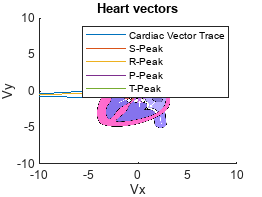



hold on % allows the graph to but laced on the heart 
title('Heart vectors') 
xlim([-10 10]);
ylim([-10 10]); % sets graph on screen properly 
a = 1000;
rind = ECG_FindR(q.i(a:a+1000))+a;
pind = ECG_FindR(q.ii(a:a+1000),'p')+a;
x = ECG_filtsig(q.vx,rind)*-1;
y = ECG_filtsig(q.vy,rind)*-1; % Sets the parameters to be used in plotting the waves, filters out the waves needed to be presented
x = smoothdata(x,"movmean","SmoothingFactor",0.25);
y = smoothdata(y,"movmean","SmoothingFactor",0.25);
tind = ECG_FindR(q.ii(a:a+1000),'t')+a;
sind = ECG_FindR(q.v2(a:a+1000),'s')+a;
plot(x(a:a+1000)*10,y(a:a+1000)*10);
hold on
plot([0,x(sind)*10],[0,y(sind)*10]);
plot([0,x(rind)*10],[0,y(rind)*10]);
plot([0,x(pind)*10],[0,y(pind)*10]);
plot([0,x(tind)*10],[0,y(tind)*10]); % Plotting the peaks from the P, R, S, and T waves of the signal
% plot(x(rind(1):rind(6)),y(rind(1):rind(6)));
t =10000;
plot([0,x(t)*10],[0,y(t)*10],"LineWidth",5);
hold off 
legend('Cardiac Vector Trace','S-Peak','R-Peak','P-Peak','T-Peak');
xlabel("Vx");
ylabel("Vy");

%problem if this is with the Dheart.mlx the heart and graph will be on the
%3D heart 